## ECE 537 : Assignment 2

Group 9 - Ashlynn Steeves, Derrell D'Souza

%close all;
%clear all;
%clc;

**Task 1** - Reload the Class A, B and C data from Exercise 1 and generated the Bayes decision boundaries for equal a priori class probabilities.

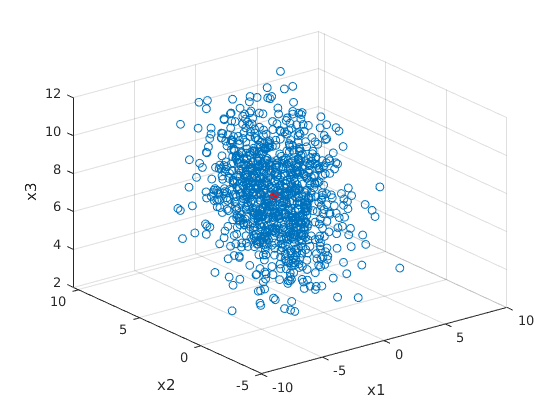

K = 1000;
D = 3;

% Dataset A
mu_A = [0 4 7];
sigma_A = [6.5000 2.1651 1.2500 ; 2.1651 5.1250 2.3816;1.2500 2.3816 2.3750];
data_A = gaussian_data(K,D,mu_A,sigma_A);

scatter3(data_A(:,1), data_A(:,2), data_A(:,3))
hold on; 
scatter3(0, 4, 7, '*r', 'LineWidth', 5.0)
xlabel('x1')
ylabel('x2')
zlabel('x3')
hold off; 


% Dataset B
mu_B = [10 5 5];
sigma_B = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456 ;-1.4481 -0.6456 1.2880];
data_B = gaussian_data(K,D,mu_B,sigma_B);

% Dataset C
mu_C = [-2 -5 -5];
sigma_C = [6.8928 -1.3750 3.1945 ;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];
data_C = gaussian_data(K,D,mu_C,sigma_C);

Vaxis = [-15 15 -15 15 -15 15];
volume = vol3D(Vaxis, 15);

pdfA = gaus_pdf(data_A, volume); % A vector of probabilities that each point is from Class A
pdfB = gaus_pdf(data_B, volume); % A vector of probabilities that each point is from Class B
pdfC = gaus_pdf(data_C, volume); % A vector of probabilities that each point is from Class C

t1_priors = [ 1/3 1/3 1/3]; % Apriori probabilites for each class 
t1_classified_pts = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t1_priors) % A matrix where the first three columns are respectivley an x, y and z coordinate and the fourth column is the classification of the point

t1_classified_pts =   -15.0000  -15.0000  -15.0000    3.0000
  -15.0000  -15.0000  -12.8571    3.0000
  -15.0000  -15.0000  -10.7143    3.0000
  -15.0000  -15.0000   -8.5714    1.0000
  -15.0000  -15.0000   -6.4286    1.0000
  -15.0000  -15.0000   -4.2857    1.0000
  -15.0000  -15.0000   -2.1429    1.0000
  -15.0000  -15.0000         0    1.0000
  -15.0000  -15.0000    2.1429    1.0000
  -15.0000  -15.0000    4.2857    1.0000



t1_classifiedA = t1_classified_pts(t1_classified_pts(:,4)==1,:) % Points classified as Class A

t1_classifiedA =   -15.0000  -15.0000   -8.5714    1.0000
  -15.0000  -15.0000   -6.4286    1.0000
  -15.0000  -15.0000   -4.2857    1.0000
  -15.0000  -15.0000   -2.1429    1.0000
  -15.0000  -15.0000         0    1.0000
  -15.0000  -15.0000    2.1429    1.0000
  -15.0000  -15.0000    4.2857    1.0000
  -15.0000  -15.0000    6.4286    1.0000
  -15.0000  -15.0000    8.5714    1.0000
  -15.0000  -15.0000   10.7143    1.0000


t1_classifiedB = t1_classified_pts(t1_classified_pts(:,4)==2,:) % Points classified as Class B

t1_classifiedB =    -4.2857   -4.2857   15.0000    2.0000
   -4.2857   -2.1429   15.0000    2.0000
   -4.2857         0   15.0000    2.0000
   -2.1429   -4.2857   15.0000    2.0000
   -2.1429   -2.1429   15.0000    2.0000
   -2.1429         0   15.0000    2.0000
         0   -6.4286   15.0000    2.0000
         0   -4.2857   15.0000    2.0000
         0   -2.1429   12.8571    2.0000
         0   -2.1429   15.0000    2.0000


t1_classifiedC = t1_classified_pts(t1_classified_pts(:,4)==3,:) % Points classified as Class C

t1_classifiedC =   -15.0000  -15.0000  -15.0000    3.0000
  -15.0000  -15.0000  -12.8571    3.0000
  -15.0000  -15.0000  -10.7143    3.0000
  -15.0000  -12.8571  -15.0000    3.0000
  -15.0000  -12.8571  -12.8571    3.0000
  -15.0000  -12.8571  -10.7143    3.0000
  -15.0000  -12.8571   -8.5714    3.0000
  -15.0000  -10.7143  -15.0000    3.0000
  -15.0000  -10.7143  -12.8571    3.0000
  -15.0000  -10.7143  -10.7143    3.0000


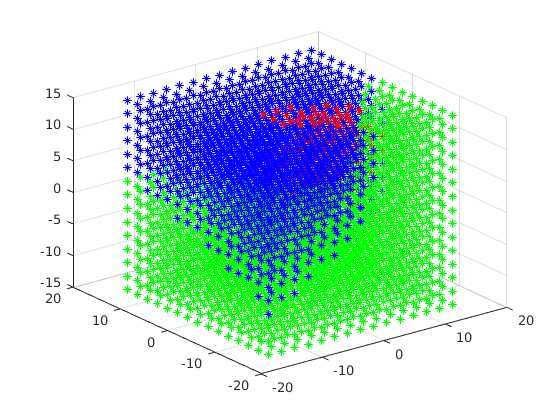


scatter3(t1_classifiedA(:,1), t1_classifiedA(:,2),t1_classifiedA(:,3), '*b')
hold on;
scatter3(t1_classifiedB(:,1), t1_classifiedB(:,2),t1_classifiedB(:,3), '*r')
scatter3(t1_classifiedC(:,1), t1_classifiedC(:,2),t1_classifiedC(:,3), '*g')
hold off

**Task 2** - Assess the degree to which changes to the means and covariance of the data classes produces changes the nature of the generated inter-class Bayes decision boundaries.

% test cases 



**Task 3 **- Show the nature of these changes by plotting the 3 data classes and their respective decision boundaries with the same 3-D plot.

% plots 


**Task 4** - Assess how these decision boundaries change with changes to the three class’s a priori probabilities.

Solution: 

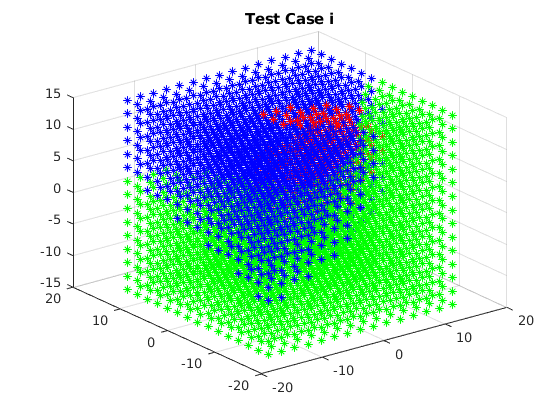

% Test case i 
t4i_priors = [1/8 1/4 5/8]; % Apriori probabilites for each class 
t4i_classified_pts = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t4i_priors); % A matrix where the first three columns are respectivley an x, y and z coordinate and the fourth column is the classification of the point

t4i_classifiedA = t4i_classified_pts(t4i_classified_pts(:,4)==1,:); % Points classified as Class A 
t4i_classifiedB = t4i_classified_pts(t4i_classified_pts(:,4)==2,:); % Points classified as Class B
t4i_classifiedC = t4i_classified_pts(t4i_classified_pts(:,4)==3,:); % Points classified as Class C

scatter3(t4i_classifiedA(:,1), t4i_classifiedA(:,2),t4i_classifiedA(:,3), '*b')
hold on;
scatter3(t4i_classifiedB(:,1), t4i_classifiedB(:,2),t4i_classifiedB(:,3), '*r')
scatter3(t4i_classifiedC(:,1), t4i_classifiedC(:,2),t4i_classifiedC(:,3), '*g')
title('Test Case i')
hold off

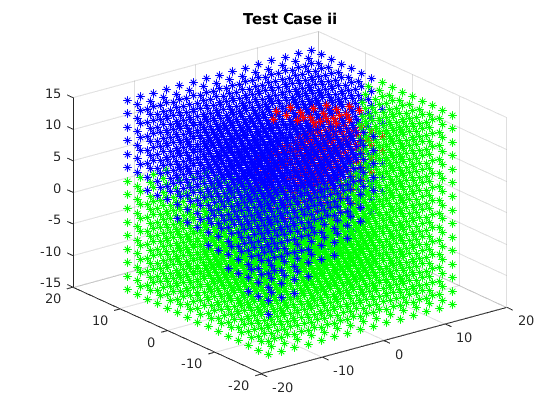



% Test Case ii 
t4ii_priors = [ 1/2 1/6 1/3]; % Apriori probabilites for each class 
t4ii_classified_pts = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t4ii_priors); % A matrix where the first three columns are respectivley an x, y and z coordinate and the fourth column is the classification of the point

t4ii_classifiedA = t4ii_classified_pts(t4ii_classified_pts(:,4)==1,:); % Points classified as Class A
t4ii_classifiedB = t4ii_classified_pts(t4ii_classified_pts(:,4)==2,:); % Points classified as Class B
t4ii_classifiedC = t4ii_classified_pts(t4ii_classified_pts(:,4)==3,:); % Points classified as Class C

scatter3(t4ii_classifiedA(:,1), t4ii_classifiedA(:,2),t4ii_classifiedA(:,3), '*b')
hold on;
scatter3(t4ii_classifiedB(:,1), t4ii_classifiedB(:,2),t4ii_classifiedB(:,3), '*r')
scatter3(t4ii_classifiedC(:,1), t4ii_classifiedC(:,2),t4ii_classifiedC(:,3), '*g')
title("Test Case ii")
hold off

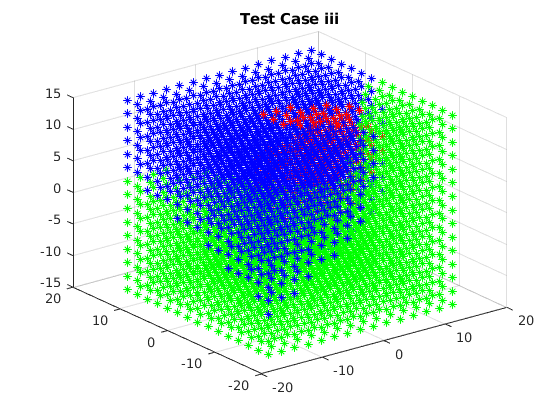



% Test case iii
t4iii_priors = [ 1/4 1/2 1/4]; % Apriori probabilites for each class 
t4iii_classified_pts = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, t4iii_priors); % A matrix where the first three columns are respectivley an x, y and z coordinate and the fourth column is the classification of the point

t4iii_classifiedA = t4iii_classified_pts(t4iii_classified_pts(:,4)==1,:); % Points classified as Class A
t4iii_classifiedB = t4iii_classified_pts(t4iii_classified_pts(:,4)==2,:); % Points classified as Class B
t4iii_classifiedC = t4iii_classified_pts(t4iii_classified_pts(:,4)==3,:); % Points classified as Class C

scatter3(t4iii_classifiedA(:,1), t4iii_classifiedA(:,2),t4iii_classifiedA(:,3), '*b')
hold on;
scatter3(t4iii_classifiedB(:,1), t4iii_classifiedB(:,2),t4iii_classifiedB(:,3), '*r')
scatter3(t4iii_classifiedC(:,1), t4iii_classifiedC(:,2),t4iii_classifiedC(:,3), '*g')
title("Test Case iii")
hold off

** Comments: **

rtgjeirtggesrng g

**Task 5 **-  Assess how these decision boundaries change with changes to the classes λAA, λAB, λAC, λBB, λBC, and, λCC loss functions, assuming λAB = λBA, λAC = λCA and λBC = λCB.

% Test Cases - zero/one loss functions or nah?? 

**Task 6 ** -  Now introduce outlier data points to one of the classes at a 10, 50, and 100 standard deviation (in what direction???) Mahalanobis distance from that class’s mean and regenerate the Bayes class boundaries.

         • Discuss the impacts that such single outlier data points can have on the resulting nature of the inter-class Bayes decision boundaries.

% Do it 
% Adding these points to Class A 

pt_mal_10 = additional_pts(mu_A, sigma_A, 10)

V =     0.0000   -0.7071   -0.7071
   -0.5000    0.6124   -0.6124
    0.8660    0.3536   -0.3536


D =     1.0000         0         0
         0    4.0000         0
         0         0    9.0000


inv_sigma =     0.1806   -0.0601   -0.0347
   -0.0601    0.3854   -0.3548
   -0.0347   -0.3548    0.7952


ans =      0
     4
     7


t =    -0.7071
   -0.6124
   -0.3536


te =    -0.7071
    3.3876
    6.6464


mah = 0.1111

Output argument "new_pt" (and maybe others) not assigned during call to "A2_draft_work>additional_pts".

%pt_mal_50 = additional_pts(mu_A, sigma_A, 50)
%pt_mal_100 = additional_pts(mu_A, sigma_A, 100)

**Task 7** -  For real-world data analysis problems, 

(a) Could the nature of the class decision boundaries effective be driven by only a few data points within the data?

(b) Is it correct (or appropriate) to have decision boundaries that exhibit high sensitivities to only a small number of data samples?

(c) How would you detect this? 

(d) How would you resolve this?

function[new_pt] = additional_pts(mu, sigma, desired_mah)
    
     [V, D] = eig(sigma)
%     [M, I] =  max(diag(D),[],1)
%     max_principal_axes = (V(:,I)+mu(I))*sqrt(D(I,I))
%     
%     xmmu = max_principal_axes-mu'
%     mah_to_stdev = sqrt(xmmu'*inv(sigma)*xmmu)
%     
%     new_mah = mah_to_stdev*desired_mah
%     
%     test = max_principal_axes*desired_mah
%     t_xmmu = test-mu'
%     t_mah = sqrt(t_xmmu'*inv(sigma)*t_xmmu)

inv_sigma = inv(sigma) 
mu'

t = (V(:,3))

te = [t(1)+mu(1); t(2)+mu(2); t(3)+mu(3)]
mah = t'*inv_sigma*t
end

function[classified_pts] = gaus_discriminant_classifier(pdfA,pdfB, pdfC, pts, prior)
    discA = log(pdfA)+log(prior(1)); % Calculate the discriminant for points belonging to Class A
    discB = log(pdfB)+log(prior(2)); % Calculate the discriminant for points belonging to Class B
    discC = log(pdfC)+log(prior(3)); % Calculate the discriminant for points belonging to Class C
    
    desc_matrix = [discA discB discC]; % Merging all discriminant values into a matrix
    [~, I] = max(desc_matrix,[], 2); % Returning the index of the largest discriminant value per row 
    % Index 1 corresponds to the point being classified as Class A, index 2
    % is Class B and index 3 is Class C.
    
    classified_pts = [pts I]; % Appending the classification of each point to the points themselves 
end 


function[pdf] = gaus_pdf(class ,pts)
    mu = mean(class); % Calculating the mean of the given class
    
    sigma = cov(class); % Calculating the covarriance of the given class
    sigma_inv = inv(sigma); % Calculating the inverse of the covarriance
    
    d = length(mu); % Determining the dimensionality of the data
    
    xmmu = pts-mu; % Subtracting the mean from each point in the dataset
    norm = (1/((2*pi)^(d/2)))*(det(sigma)^(-1/2)); % Calculating the normalization constant (from the multivarriate gaussian eq)
    exp_term = zeros(length(xmmu),1); % Initializing the vector of exponential terms 
    
    for i = 1:length(xmmu)
        exp_term(i) = -1/2*xmmu(i,:)*sigma_inv*xmmu(i,:)'; % Calculating the term that will be in the exponent (from the multivarriate gaussian eq) for each datapoint
    end
    
    pdf = norm*exp(exp_term); % Combining terms to generate the probability that a point is from the given class
end


function f = gaussian_data(K,D,mu,sigma)
    N = randn(K,D); % Generate a subset of K D-dimensional samples from a normal distribution
    N_c = N - mean(N); % Centralize the data at zero-mean
    
    [v,d] = eig(cov(N_c)); % Obtain eigen values and eigen vectors for covariance of N    
    R = v*inv(sqrt(d)); % Generate the whitening transform
    W  = N_c*R; % Apply the whitening transform on the centralized data
    
    [vn,dn] = eig(sigma); % Obtain eigen values and eigen vectors of the desired covariance
    R_inv = sqrt(dn)*inv(vn); % Generate the inverse whitening transform
    f = W*R_inv; % Apply the inverse whitening transfrom on the whitened gaussian data 
    f = f + mu; % Centralize the data at the desired mu
end 

function V = vol3D(Vaxis,Num)

NV = Num;

if length(Vaxis) == 2
    Vaxis = [Vaxis Vaxis Vaxis];
end

min_a = Vaxis(1);
max_a = Vaxis(2);
res = (max_a-min_a)/(NV-1);

r = min_a:res:max_a;
r = r(:);

rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';

x = zeros(3,length(rz)^3);
k =1;
j = 1;
for i = 1:length(rz):length(x)
    x(3,(i-1)+(1:length(rz)))= rz;
    x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
    x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
    k = k+1;
    if k > length(rz)
        k =1;
        j = j +1;
    end
end
x = x';
V = x;

end